# 异常值和缺失值的处理

**作者：《数学建模学习交流》清风**

在对数据进行预处理中，我们经常会遇到异常值和缺失值的情况，下面我们对这两种情况的常用技术进行介绍，希望能帮到大家。

在数据既有异常值又有缺失值时，先处理哪个并没有严格的顺序。我习惯先处理异常值，再处理缺失值。

# **异常值的识别方法**

异常值，指的是样本中的一些数值明显偏离其余数值的样本点，所以也称为离群点。常见的异常值判断方法可以分为以下两种情况：

## **（1）数据有一个给定范围**

例如调查问卷中，需要对某个事物进行打分，满分为0-10分。如果填问卷的人填了一个30分，那么这个数据就是异常值。

这种情况比较简单，我们可以使用MATLAB的逻辑运算快速的找到这些异常值：

x = [8 9 10 7 6 3 30 4 13 9 2];
x<0 | x>10  % | 表示或运算

ans = 1×11 logical 数组
   0   0   0   0   0   0   1   0   1   0   0


ind = find(x<0 | x>10)

ind =      7     9


x(ind)   % 也可以直接使用x(x<0 | x>10)

ans =     30    13


返回7和9，意味着第7个位置和第9个位置的元素不在0-10的范围内。

## （2） **数据没有给定的范围**

这种情况下我们介绍两种最常用的判定方法：

- **第一：****3**$\sigma$**原则识别异常值**

下面给出MATLAB的代码(MATLAB版本2017a，其他低版本请自行测试)：

x = [48 51 57 57 49 86 48 53 59 50 48 47 53 56 60];   % 假设x是取自正态分布的样本
u = mean(x,'omitnan');  % 忽略数据中的缺失值计算均值
sigma = std(x,'omitnan');   % 计算标准差  std(x,0,'omitnan')是总体标准差
lb = u - 3*sigma    % 区间下界，low bound的缩写

lb = 25.8202

ub = u + 3*sigma   % 区间上界，upper bound的缩写

ub = 83.7798

tmp = (x < lb) | (x > ub);
ind = find(tmp)

ind = 6

返回6，意味着第6个位置是异常值

- **第二：**$\mathbf{箱}\mathbf{线}\mathbf{图}\mathbf{识}\mathbf{别}\mathbf{异}\mathbf{常}\mathbf{值}$

**和3**$\sigma$**原则相比，箱线图并没有对数据服从的分布作任何限制性要求（3**$\sigma$**原则要求数据服从正态分布或近似服从正态分布），其判断异常值的标准主要以四分位数和四分位距为基础。在总体分布未知的情况下，使用箱线图识别异常值的结果更加客观。**

x = [48 51 57 57 49 86 48 53 59 50 48 47 53 56 60];
% 计算分位数的函数需要MATLAB安装了统计机器学习工具箱
Q1 = prctile(x,25); % 下四分位数
Q3 = prctile(x,75); % 上四分位数
IQR = Q3-Q1; % 四分位距
lb = Q1 - 1.5*IQR % 下界

lb = 35.1250

ub = Q3 + 1.5*IQR % 上界

ub = 70.1250

tmp = (x < lb) | (x > ub);
ind = find(tmp)

ind = 6

返回6，意味着第6个位置是异常值

## **识别出异常值后，我们通常可以将异常值视为缺失值，然后交给缺失值处理方法来处理。**

代码：

x

x =     48    51    57    57    49    86    48    53    59    50    48    47    53    56    60


ind

ind = 6

x(ind) = nan % 这里的nan表示非数字Not-a-Number,例如0/0就会返回nan，我们这里可以用nan代表数字中的缺失值

x =     48    51    57    57    49   NaN    48    53    59    50    48    47    53    56    60


 （注意：如果有多列数据都需要处理，我们可以写一个循环，这里就不展开了。）

# **缺失值的处理**

## 计算缺失值数量

MATLAB中计算缺失值数量的函数非常简单，我们可以使用ismissing函数和sum函数，下面举个例子：

A = [3 NaN 5 6 7 NaN NaN 9];  % nan也可以写成NaN
TF = ismissing(A)

TF = 1×8 logical 数组
   0   1   0   0   0   1   1   0


`% TF = 1x8 ``的逻辑数组（为``1``的位置表示是缺失值）`

sum(TF)

ans = 3

`对``TF``向量求和，结果为``3``，代表有``3``个缺失值`

另外，ismissing函数也可以对矩阵或者表格数据类型判断缺失值，有兴趣的同学可以查询MATLAB官网。[https://www.mathworks.cn/help/matlab/ref/ismissing.html](https://www.mathworks.cn/help/matlab/ref/ismissing.html)

B = [1 2 5;
    nan 0 8;
    nan 1 nan;
    3 5 nan;
    nan nan nan];
TF = ismissing(B)

TF = 5×3 logical 数组
   0   0   0
   1   0   0
   1   0   1
   0   0   1
   1   1   1


sum(TF,1) % 计算每一列的和

ans =      3     1     3


sum(TF,2)  % 计算每一行的和

ans =      0
     1
     2
     1
     3


如果想删除缺失值怎么办？

B = [1 2 5;
    nan 0 8;
    nan 1 nan;
    3 5 nan;
    nan nan nan];

删除第五行

B(5,:) = []

B =      1     2     5
   NaN     0     8
   NaN     1   NaN
     3     5   NaN


删除第三列

B(:,3) =[]

B =      1     2
   NaN     0
   NaN     1
     3     5


## **缺失值填补**

**下面我们再来介绍缺失值填补，我们需要对缺失的数据类型进行区分：横截面数据和时间序列数据。这两种数据的缺失值处理方法有所不同。**

横截面数据是指在某一时点收集的不同对象的数据，例如北京、上海、广州、深圳等30个城市今天的最高气温；时间序列数据是指对同一对象在不同时间连续观察所取得的数据，例如北京今年来每天的最高气温。

**对于横截面数据，我们通常使用某个具体的数值来代替缺失值，例如非缺失数据的平均值、中位数或者众数。**

MATLAB的fillmissing函数可以很方便的帮助我们实现这个功能。

*语法：**F = fillmissing(A,'constant',v) **使用常数**v **填充缺失的数组或表。*

A = [2 3 nan 3 nan nan 8 4];
v = mean(A,'omitnan');  % 平均值
% v = median(A,'omitnan');  % 中位数
% v = mode(A);  % 众数，常用于离散变量的缺失值
F = fillmissing(A,'constant',v)

F =      2     3     4     3     4     4     8     4


**对于数据序列数据，我们通常有下面几种策略：**

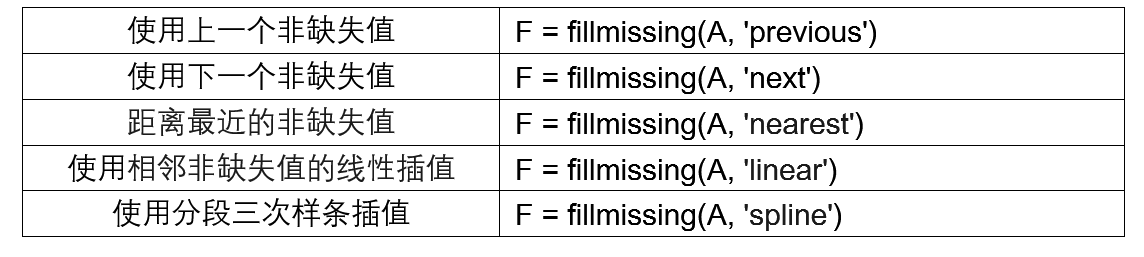

A = [10 12 16 23 nan 49 68];
F1 = fillmissing(A, 'previous')

F1 =     10    12    16    23    23    49    68


F2 = fillmissing(A, 'next')

F2 =     10    12    16    23    49    49    68


F3 = fillmissing(A, 'nearest')  % 距离同样近时选择右侧的

F3 =     10    12    16    23    49    49    68


F4 = fillmissing(A, 'linear')

F4 =     10    12    16    23    36    49    68


F5 = fillmissing(A, 'spline')

F5 =    10.0000   12.0000   16.0000   23.0000   33.9626   49.0000   68.0000
